This notebook is used to produce the different required plots for the kirigami parachute article.

## **Data loading section**

clear all; close all; clc;

%Adding path
path('.\', path);

%Set font sizes
set(groot,'defaultAxesFontSize',12)

% This script undocks the figures. 
% list_factory = fieldnames(get(groot,'factory'));
% index_visible = find(contains(list_factory,'Visible'));
% for i = 1:length(index_visible)
%     default_name = strrep(list_factory{index_visible(i)},'factory','default');
%     set(groot, default_name,'on');
% end

% This script changes all interpreters from text to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

dh = 0.516; %width difference in figures
dw = 0.19350; %height difference in figures

%Loading specimens definitions
excelSheet = "Experiments/AngularSpecimens/Specimens.xlsx";
defs = readtable(excelSheet, "sheet", "Definition");
temp = defs.Properties.VariableNames(2:end);
all_names = {};
for i = 1:length(temp)
    all_names{end+1} = temp{i};
end
defs = table2array(defs(:,2:end));

%Disk parameters
Rs = defs(1, :)*10^(-3);
Rc = defs(3, :)*10^(-3);
t = defs(4,:)*10^(-6);
tcut = 0.1E-3;
beta = Rs./Rc;
A = pi*(Rs.^2);% - Rc.^2);

%Material parameters
E = 3E9;
nu = 0.3;
B = E.*t.^3/(12*(1-nu^2));

%Flow parameters
rho = 1.225;

res = open("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = res.D;
UR = res.U;

p = polyfit(UR, DR, 2);
CD0 = p(1)/(0.5*rho*A(1));

%CD0 = 1.1;
g = 9.81; %m/s

%Pattern parameters associated with specimens
drmin = defs(5,:)*10^(-3);
Ntheta = defs(6,:);
n = defs(7,:);
rtheta = defs(8,:);
Nr = defs(17,:);

%Unique parameters
ts = unique(t);
drmins = unique(drmin);
ns = unique(n);
Nthetas = unique(Ntheta);
rthetas = unique(rtheta);

%Properties
Kexp = defs(11, :);

%Unique colors
white = [1,1,1];
black = [0,0,0];
%green = [75, 204, 40]/256;
%blue = [10, 157, 255]/256;
red = [256,0,0]/256;
orange = [255, 201, 40]/256;
purple = [142, 76, 167]/256;
yellow = [249, 251, 21]/256;
grey = [142,156,165]/255;

green = sscanf("6CBA7D",'%2x%2x%2x',[1 3])/255;
blue = sscanf("6CB0D6",'%2x%2x%2x',[1 3])/255;

greenmap = @(len) [linspace(green(1), blue(1), len)', linspace(green(2), blue(2), len)', linspace(green(3), blue(3), len)'];
bluemap = [linspace(0, blue(1), 100), linspace(0, blue(2), 100), linspace(0, blue(3), 100)];
redmap = [linspace(0, red(1), 100), linspace(0, red(2), 100), linspace(0, red(3), 100)];

low = sscanf("40AD5A",'%2x%2x%2x',[1 3])/255;
mid = grey;
high = sscanf("3C93C2",'%2x%2x%2x',[1 3])/255;

sequentialmap = @(len) [linspace(low(1), high(1), len)', linspace(low(2), high(2), len)', linspace(low(3), high(3), len)'];

% colorst = greenmap(length(ts));
% colorsdr = greenmap(length(drmins));
% colorsn = greenmap(length(ns));
% colorsNtheta = greenmap(length(Nthetas));
% colorsrtheta = greenmap(length(rthetas));

% colorst = sequentialmap(length(ts));
% colorsdr = sequentialmap(length(drmins));
% colorsn = sequentialmap(length(ns));
% colorsNtheta = sequentialmap(length(Nthetas));
% colorsrtheta = sequentialmap(length(rthetas));

colorst = flipud(winter(length(ts)));
colorsdr = flipud(winter(length(drmins)));
colorsn = flipud(winter(length(ns)));
colorsNtheta = flipud(winter(length(Nthetas)));
colorsrtheta = flipud(winter(length(rthetas)));

%Simulation data
%Mode K No gravity
res = open("CorotationalReconfiguration/kirigami_disk/AK/AK8/NoGravity/data.mat");
deltasimK = res.delta;
CYsimK = res.CY;
RsimK = res.R;

%Mode K more flexible
res = open("CorotationalReconfiguration/kirigami_disk/AK/AK52/NoGravity/data.mat");
deltasimK2 = res.delta;
CYsimK2 = res.CY;
RsimK2 = res.R;

%Mode K theo
res = open("kirigamiBeams/AK8/Reconfiguration/data.mat");
deltatheoK = res.delta;
CYtheoK = res.CY;
RtheoK = res.R;

%Mode K theo more flexible
res = open("kirigamiBeams/AK52/data.mat");
deltatheoK2 = res.delta;
CYtheoK2 = res.CY;
RtheoK2 = res.R;

%Mode C No Gravity
res = open("CorotationalReconfiguration/kirigami_disk/AK/AK10/NoGravity/data.mat");
deltasimC = res.delta;
CYsimC = res.CY;
RsimC = res.R;
% 
%Mode K Traction
res = open("CorotationalReconfiguration/kirigami_disk/AK/AK8/Traction/data.mat");
FsimK = res.F;
wsimK = res.w;

res = open("CorotationalReconfiguration/kirigami_disk/AK/AK52/Traction/data.mat");
FsimK2 = res.fs;
wsimK2 = res.ymax;

% 
%Mode C Traction
res = open("CorotationalReconfiguration/kirigami_disk/AK/AK10/Traction/data.mat");
FsimC = res.F;
wsimC = res.w;
% 
% %Semi-analytical data
% %Theorical mode K
% %Traction
res = open("kirigamiBeams/AK8/Traction/wF.mat");
wtheoK = res.w;
FtheoK = res.F';
% 
% %Reconfiguration
% res = open("kirigamiBeams/AK8/Reconfiguration/ULD.mat");
% UtheoK = res.U';
% LtheoK = res.L;
% DtheoK = res.D;
% 
% %Porous Reconfiguration
% res = open("kirigamiBeams/AK8/PorousReconfiguration/ULD.mat");
% UtheoKPorous = res.U';
% LtheoKPorous = res.L;
% DtheoKPorous = res.D;
% 
%Theorical mode C
%Traction
res = open("kirigamiBeams/AK10/Traction/wF.mat");
wtheoC = res.w;
FtheoC = res.F';
% 
% %Reconfiguration
res = open("kirigamiBeams/AK10/Reconfiguration/ULD.mat");
UtheoC = res.U';
LtheoC = res.L;
DtheoC = res.D;

%Loading tensile data
path = "Experiments\AngularSpecimens\Tensile\";
list = dir(path);
disp = cell(1, length(all_names));
force = disp;
%Kexp = zeros(1, length(all_names));
for i = 1:length(list)
    item = list(i).name;
    if length(list(i).name(:)) > 2
        if list(i).name(end-3:end) == ".txt"
            name = item(1:end-4);
            if any(strcmpi(all_names,name))
                ind = find(strcmpi(all_names,name));
                data = table2array(readtable(path+item));
                index = 0;
                for j = 1:length(all_names)
                    if strcmpi(all_names{j}, item(1:end-4))
                        index = j;
                        break;
                    end
                end
                
                startforce = [];
                startdisp = [];
                newforce = [];
                newdisp = [];
                for j = 1:length(data(:,1))
                    if data(j,3) >= 5
                        startforce = -data(j:end, 2) + data(j,2);
                        startdisp = data(j:end,3) - data(j,3);
                        break
                    end
                end
                
                for j = 2:length(startdisp)
                    if startdisp(j) > startdisp(j-1)
                        newforce(end+1) = startforce(j);
                        newdisp(end+1) = startdisp(j);
                    else
                        break;
                    end
                end
                
                force(ind) = {newforce};
                disp(ind) = {newdisp/1000};

%                 [wsort, index] = sort(newdisp/1000);
%                 fsort = newforce(index);
%                 
%                 for j = 15:length(wsort)
%                     mdl = fitlm(wsort(5:j), fsort(5:j));
%                     r2 = mdl.Rsquared.Ordinary;
%                     if r2 < 0.99
%                         diff = j - 1;
%                         break;
%                     end
%                     if j == length(wsort)
%                         diff = j;
%                     end
%                 end
%                 
%                 linforce = fsort(5:diff-1);
%                 lindisp = wsort(5:diff-1);
%                 p = polyfit(lindisp, linforce, 1);
%                 Kexp(ind) = p(1);
            end
        end
    end
end

forcedisp = {};

for i = 1:length(disp)
    for j = 1:length(disp{i})
        forcedisp{j,2*(i-1)+1} = disp{i}(j);
        forcedisp{j,2*(i-1)+2} = force{i}(j);
    end
end


%Classifying specimens
modes = cell(1, length(all_names));
markers = cell(1, length(all_names));
colors = cell(1, length(all_names));
series = cell(1, length(all_names));
B = zeros(1, length(all_names));
Kbar = zeros(1, length(all_names));
ell = zeros(1, length(all_names));
epsKC = zeros(1, length(all_names));
lambdas = zeros(1, length(all_names));


Modes = readtable(excelSheet, "sheet", "Modes");

%Specimen loop
for j = 1:length(all_names)
    %Identifying the mode
    if strcmpi(Modes{1,j+2}, "C")
        modes{j} = "o";
    elseif strcmpi(Modes{1,j+2}, "K")
        modes{j} = "diamond";
    elseif strcmpi(Modes{1,j+2}, "K*")
        modes{j} = "square";
    elseif strcmpi(Modes{1,j+2}, "3K")
        modes{j} = "hexagram";
    end

    %Identify which series we are in
    cond1 = (Rs(j) == 70E-3);
    cond2 = (t(j) == 75E-6);
    cond3 = (drmin(j) == 2E-3);
    cond4 = (n(j) == 1);
    cond5 = (Ntheta(j) == 5);
    cond6 = (rtheta(j) == 0.3);
    
    if cond1 && cond2 && cond3 && cond4 && cond5 && cond6
        %basecase
        markers{j} = "o";
        colors{j} = [0,0,0];
        series{j} = "base";
    elseif cond1 && cond6 && cond3 && cond4 && cond5
        %t
        ind = find(t(j) == ts);
        markers{j} = "pentagram";
        colors{j} = colorst(ind,:);
        series{j} = "t";
    elseif cond1 && cond2 && cond6 && cond4 && cond5
        %dr
        ind = find(drmin(j) == drmins);
        markers{j} = "square";
        colors{j} = colorsdr(ind,:);
        series{j} = "dr";
    elseif cond1 && cond2 && cond3 && cond6 && cond5
        %n
        ind = find(n(j) == ns);
        markers{j} = "diamond";
        colors{j} = colorsn(ind,:);
        series{j} = "n";
    elseif cond1 && cond2 && cond3 && cond4 && cond6
        %Ntheta
        ind = find(Ntheta(j) == Nthetas);
        markers{j} = "hexagram";
        colors{j} = colorsNtheta(ind,:);
        series{j} = "Ntheta";
    elseif cond1 && cond2 && cond3 && cond4 && cond5
        %rtheta
        ind = find(rtheta(j) == rthetas);
        markers{j} = "^";
        colors{j} = colorsrtheta(ind,:);
        series{j} = "rtheta";
    end

    %Calculating properties
    [Kbari, elli, epsKCi, lambdai, slitLengthi] = getKirigamiValues(Rs(j), Rc(j), 1.35E-3, drmin(j)./Rs(j), n(j), Ntheta(j), rtheta(j));
    Kbar(j) = Kbari; ell(j) = elli; epsKC(j) = epsKCi; B(j) = E*t(j)^3/12; A(j) = A(j) - slitLengthi*tcut;
    lambdas(j) = lambdai;
end

## **Tensile tests section**

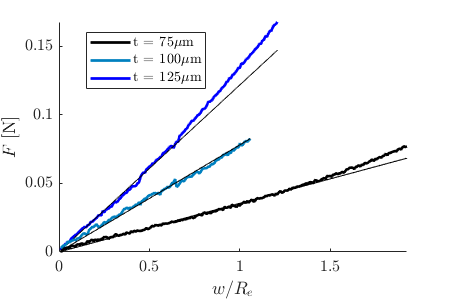

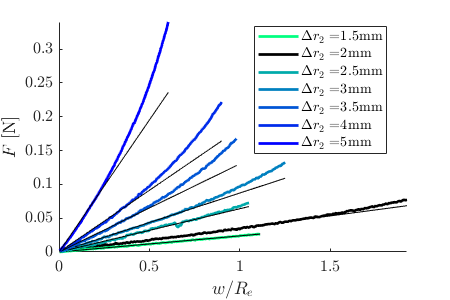

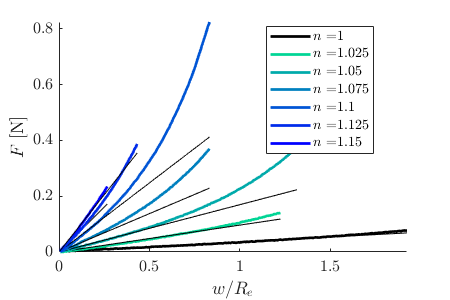

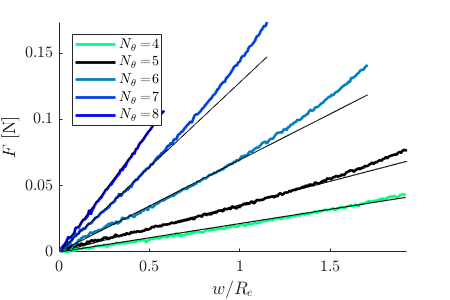

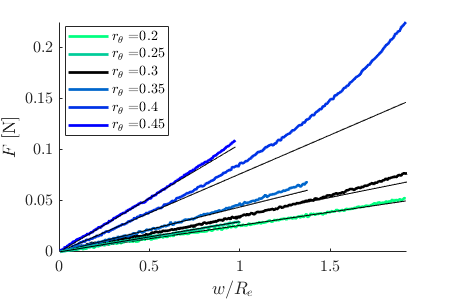


%Plotting force-extension plots
f1 = figure("Name", "Tensile t", 'Position', [50 150 450 300]); %Tensile t
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f2 = figure("Name", "Tensile dr", 'Position', [50 150 450 300]); %Tensile dr
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f3 = figure("Name", "Tensile n", 'Position', [50 150 450 300]); %Tensile n
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f4 = figure("Name", "Tensile Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f5 = figure("Name", "Tensile rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");

torder = []; tplots = gobjects(length(ts), 1);
drorder = [];drplots = gobjects(length(drmins), 1);
norder = []; nplots = gobjects(length(ns), 1);
Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);

for j = 1:length(all_names)
    switch series{j}
        case "base"
            for i = 1:5
                switch i
                    case 1
                        figure(f1);
                        ind = find(t(j) == ts);
                        tplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
                        torder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 2
                        figure(f2);
                        ind = find(drmin(j) == drmins);
                        drplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
                        
                        drorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 3
                        figure(f3);
                        ind = find(n(j) == ns);
                        nplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$n = $"+num2str(n(j)));
                        
                        norder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 4
                        figure(f4);
                        ind = find(Ntheta(j) == Nthetas);
                        Nthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
                        
                        Nthetaorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 5
                        figure(f5);
                        ind = find(rtheta(j) == rthetas);
                        rthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$r_\theta = $"+num2str(rtheta(j)));
                        
                        rthetaorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                end
            end
        case "t"
            figure(f1);
            ind = find(t(j) == ts);
            tplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
            
            torder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "dr"
            figure(f2);
            ind = find(drmin(j) == drmins);
            drplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
            
            drorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "n"
            figure(f3);
            ind = find(n(j) == ns);
            nplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$n = $"+num2str(n(j)));
            
            norder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "Ntheta"
            figure(f4);
            ind = find(Ntheta(j) == Nthetas);
            Nthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
            
            Nthetaorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "rtheta"
            figure(f5);
            ind = find(rtheta(j) == rthetas);
            rthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$r_\theta = $"+num2str(rtheta(j)));
            
            rthetaorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
    end
end
%Reorder legends and correct limits
for i = 1:5
    xlim([0, inf]);
    ylim([0, inf]);
    switch i
        case 1
            figure(f1);
            legend(tplots, "Location", "best");
            figureSaver(f1, "bruteFigs/tensilet.pdf");
        case 2
            figure(f2);
            legend(drplots, "Location", "best");
            figureSaver(f2, "bruteFigs/tensiledr.pdf");
        case 3
            figure(f3);
            legend(nplots, "Location", "best");
            figureSaver(f3, "bruteFigs/tensilen.pdf");
        case 4
            figure(f4);
            legend(Nthetaplots, "Location", "best");
            figureSaver(f4, "bruteFigs/tensileNtheta.pdf");
        case 5
            figure(f5);
            legend(rthetaplots, "Location", "best");
            figureSaver(f5, "bruteFigs/tensilertheta.pdf");
    end
end

%Comparison experimental stiffness - stiffness model
f12 = figure("Name", "StiffComp", 'Position', [50 150 450 300]);
hold on;
ylabel("$K$ [N/m]");
xlabel("$\tilde{K}=B\bar{K}/R_e^2$ [N/m]");
Ktheo = Kbar.*B./Rs.^2;
for j = 1:length(all_names)
    scatter(Ktheo(j), Kexp(j), "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j});
end
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis("tight");
p = polyfit(log10(Ktheo), log10(Kexp), 1);
pK = p;
fprintf("Order of the fit = "+num2str(p(1))+" which means Ktheo scales with K");

Order of the fit = 0.97596 which means Ktheo scales with K

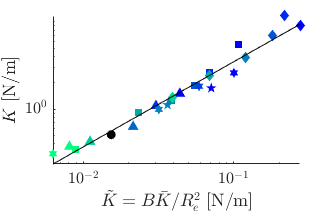

x = [min(Ktheo), max(Ktheo)];
plot(x, 10.^polyval(p, log10(x)), "-k");
f12.Units = "centimeters";
f12.Position = [1 1 8.7624 5.6471];
f12.Units = "points";
figureSaver(f12, "bruteFigs/stiffComp.pdf");

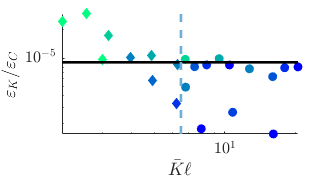

%Phase diagram
f1 = figure("Name", "Transition");
hold on;
xlabel("$\bar{K}\ell$");
ylabel("$\varepsilon_K/\varepsilon_C$")
for j = 1:length(all_names)
    scatter(Kbar(j)*ell(j), epsKC(j), "marker", modes{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j});
end
axis("tight");
xs = xlim();
ys = ylim();
plot(xs, [9,9]/10^6, "-k", "linewidth", 2);
plot([6.5,6.5], ys, "--", "color", blue, "linewidth", 2);
xlim([xs(1)*0.9, xs(2)*1.1]); ylim([ys(1)*0.9, ys(2)*1.1]);
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis("tight");
f1.Units = "centimeters";
f1.Position = [1 1 8.7168, 4.8114];
figureSaver(f1, "bruteFigs/transition.pdf");

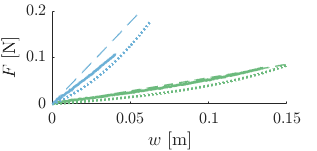

%Comparing dimensional tensile tests to numerical and semi-analytical
%results

f1 = figure("Name", "TensileCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$w$ [m]");
ylabel("$F$ [N]");

h = gobjects(6,1);

%AK8
%Exp
h(1) = plot(disp{1}, force{1}, "color", green, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
h(2) = plot(wsimK, FsimK, ":", "color", green, "linewidth", 2, "DisplayName", "FEM");
[wsort, ind] = sort(wsimK);
fsort = FsimK(ind);

for i = 10:length(wsort)
    mdl = fitlm(wsort(5:i), fsort(5:i));
    r2 = mdl.Rsquared.Ordinary;
    if r2 < 0.995
        diff = i - 1;
        break;
    end
    if i == length(wsort)
        diff = i;
    end
end

linforce = fsort(5:diff-1);
lindisp = wsort(5:diff-1);
p = polyfit(lindisp, linforce, 1);
KsimK = p(1);

%Theo
Ktheoi = Ktheo(1);
ratio = 10.^polyval(pK, log10(Ktheoi))/Ktheoi;
h(3) = plot(wtheoK, FtheoK*ratio, "--", "color", green, "linewidth", 1, "DisplayName", "Corrected Nonlinear Beam Model");


%AK10
%Exp
h(4) = plot(disp{3}, force{3}, "color", blue, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
h(5) = plot(wsimC, FsimC, ":", "color", blue, "linewidth", 2, "DisplayName", "FEM");
[wsort, ind] = sort(wsimC);
fsort = FsimC(ind);

for i = 10:length(wsort)
    mdl = fitlm(wsort(5:i), fsort(5:i));
    r2 = mdl.Rsquared.Ordinary;
    if r2 < 0.995
        diff = i - 1;
        break;
    end
    if i == length(wsort)
        diff = i;
    end
end

linforce = fsort(5:diff-1);
lindisp = wsort(5:diff-1);
p = polyfit(lindisp, linforce, 1);
KsimC = p(1);

%Theo
Ktheoi = Ktheo(3);
ratio = 10.^polyval(pK, log10(Ktheoi))/Ktheoi;
h(6) = plot(wtheoC, FtheoC*ratio, "--", "color", blue, "linewidth", 1, "DisplayName", "Corrected Nonlinear Beam Model");

%legend(h, "location", "best");
%axis("tight");
xlim([0, 0.15]);
ylim([0, 0.2]);
f1.Units = "centimeters";
f1.Position = [1 1 8.4 4];
f1.Units = "points";
figureSaver(f1, "bruteFigs/TensileCompModels.pdf");

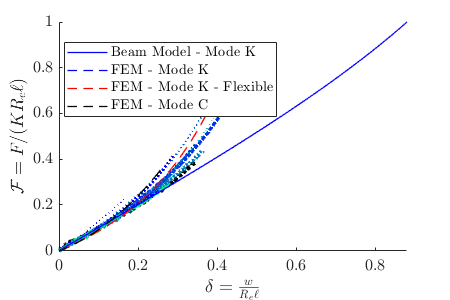

%Dimensionless tensile test
f11 = figure("Name", "Dimensionless Tensile", 'Position', [50 150 450 300]);
hold on;
%xlabel("$w [m]$")
%ylabel("$F [N]$")
xlabel("$\delta = \frac{w}{R_e\ell}$")
ylabel("$\mathcal{F} = F/(KR_e\ell)$")
for j = 1:length(all_names)
    Fmax = Kexp(j)*Rs(j)*ell(j);
    switch series{j}
        case "base"
            line = ":";
            width = 3;
        case "t"
            line = ":";
            width = 0.5;
        case "dr"
            line = ":";
            width = 2;
        case "n"
            line = ":";
            width = 1;
        case "Ntheta"
            line = ":";
            width = 1.5;
        case "rtheta"
            line = ":";
            width = 2.5;
    end
    plot(disp{j}/(Rs(j)*ell(j)), force{j}/(Kexp(j)*Rs(j)*ell(j)), "color", colors{j}, "linestyle", line, "linewidth", width);
end

%Tensile theoretical model (linear and nonlinear)
h = gobjects(4,1);

h(1) = plot(wtheoK/(Rs(1)*ell(1)), FtheoK/(Ktheo(1)*Rs(1)*ell(1)), "-b", "linewidth", 1, "DisplayName", "Beam Model - Mode K");
%h(2) = plot(wtheoC/(Rs(3)*ell(3)), FtheoC/(Ktheo(3)*Rs(3)*ell(3)), "-r", "linewidth", 1, "DisplayName", "Beam Model - Mode C");
h(2) = plot(wsimK/(Rs(1)*ell(1)), FsimK/(KsimK*Rs(1)*ell(1)), "--b", "linewidth", 1, "DisplayName", "FEM - Mode K");
h(3) = plot(wsimK/(Rs(1)*ell(1)), FsimK/(KsimK*Rs(1)*ell(1)), "--r", "linewidth", 1, "DisplayName", "FEM - Mode K - Flexible");
h(4) = plot(wsimC/(Rs(3)*ell(3)), FsimC/(KsimC*Rs(3)*ell(3)), "--k", "linewidth", 1, "DisplayName", "FEM - Mode C");
axis("tight");
legend(h, "location", "best");
figureSaver(f11, "bruteFigs/dimensionlessTensileComp.pdf");

## **Windtunnel drag section**

%Windtunnel data from Montreal
velocity = cell(1, length(all_names));
drag = cell(1, length(all_names));
extension = cell(1, length(all_names));

cd Experiments\AngularSpecimens\;

folders = dir();
for i = 3:length(folders)
    if isfolder(folders(i).name) && ~strcmpi(folders(i).name, "Rigid") ...
            && ~strcmpi(folders(i).name, "Empty") && ~strcmpi(folders(i).name, "Assembled") ...
            && ~strcmpi(folders(i).name, "drawings") && ~strcmpi(folders(i).name, "Obsolete") ...
            && ~strcmpi(folders(i).name, "Tensile")
        load(folders(i).name+"\UDL.mat");
        for j = 1:length(all_names)
            if strcmpi(folders(i).name, all_names{j})
                break;
            end
        end
        velocity{j} = U;
        drag{j} = D;
        extension{j} = L;
        
        if strcmpi(folders(i).name, "AK10")
            modes{j} = "o";
        else
            modes{j} = "diamond";
        end
    end
end

cd ..\..;

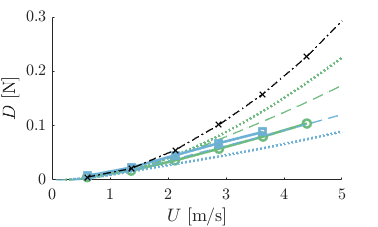

%Comparing dimensional drag results tests to numerical and semi-analytical
%results

f1 = figure("Name", "DragCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");

h = gobjects(7,1);

%AK8
%Exp
h(1) = plot(velocity{1}, drag{1}, "-o", "color", green, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
U = sqrt(CYsimK*KsimK*ell(1)/(CD0*rho*Rs(1)));
D = RsimK.*0.5*rho*CD0*A(1).*U.^2;
h(2) = plot(U, D, ":", "color", green, "linewidth", 2, "DisplayName", "FIRM");

%Theo
U = sqrt(CYtheoK*Ktheo(1)*ell(1)/(CD0*rho*Rs(1)));
D = RtheoK.*0.5*rho*CD0*A(1).*U'.^2;
h(3) = plot(U, D, "--", "color", green, "linewidth", 1, "DisplayName", "Nonlinear Beam Model");

%AK10
%Exp
h(4) = plot(velocity{3}, drag{3}, "-s", "color", blue, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
U = sqrt(CYsimC*2*B(3)/(CD0*rho*Rs(3)^3));
D = RsimC.*0.5*rho*CD0*A(3).*U.^2;
h(5) = plot(U, D, ":", "color", blue, "linewidth", 2, "DisplayName", "FIRM");

%Theo
h(6) = plot(UtheoC, DtheoC, "--", "color", blue, "linewidth", 1, "DisplayName", "Nonlinear Beam Model");

%Rigid
res = open("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = res.D;
UR = res.U;
h(7) = plot(UR, DR, "-.xk", "linewidth", 1, "DisplayName", "Rigid");

%legend(h, "location", "best");
%axis("tight");
xlim([0, 5]);
ylim([0, 0.3]);
f1.Units = "centimeters";
f1.Position = [1 1 10 6];
f1.Units = "points";
figureSaver(f1, "bruteFigs/DragCompModels.pdf");

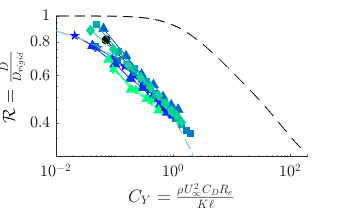

%Dimensionless drag
f1 = figure("Name", "Dimensionless drag", 'Position', [50 150 450 300]);
hold on;
xlabel("$C_Y = \frac{\rho U_\infty^2 C_DR_e}{K\ell}$")
ylabel("$\mathcal{R} = \frac{D}{D_{rigid}}$")

%allx = linspace(0, 0.01, 50);
%ally = ones(size(allx));

allx = []; ally = [];

load("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = D;

for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 2:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
            CYCD = CD0*(rho*velocity{j}(i)^2*Rs(j))/(Kexp(j)*ell(j));
            %D = drag{j}(i)/(Ktheo(j)*Ls(j));
            R = drag{j}(i)/DR(i);
            currentx(end+1) = CYCD;
            currenty(end+1) = R;
            allx(end+1) = CYCD;
            ally(end+1) = R;
        end
    end
    if strcmpi(modes{j}, "diamond")
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 0.5);

    end
end

%save("ReconfExp.mat", "allx", "ally");

h = gobjects(2,1);

h(1) = plot(CYsimK, RsimK, "--k", "DisplayName", "FIRM");
axis("tight");
%h(2) = plot(CYsimK2, RsimK2, "--r", "DisplayName", "FIRM - Flexible");

% CYtheoK = CD0*rho*Rs(1)^3*UtheoK.^2/(B(1)*Kbar(1)*ell(1));
% RtheoK = DtheoK./(0.5*rho*CD0*A(1)*UtheoK.^2);
%h(3) = plot(CYtheoK, RtheoK, "-k", "DisplayName", "Beam Model");
%h(4) = plot(CYtheoK2, RtheoK2, "-r", "DisplayName", "Beam Model - Flexible");
% 
% 
b = @(x, CYCD) 1./(1+x(1)*CYCD.^x(2));
RsimKModel = @(x, CYCD) extrapolatereconf(CYsimK, RsimK, CYCD)'.*b(x, CYCD);

x1 = fminsearch(@(x) getRegressionError(allx, ally, @(CYCD) RsimKModel(x, CYCD)), [1, 0.5]);
b = @(CYCD) b(x1, CYCD);
RsimKModel = @(CYCD) RsimKModel(x1, CYCD);
h(2) = plot(CYsimK, RsimKModel(CYsimK), "--", "color", blue, "DisplayName", "FIRM - Corrected");

% load("Experiments/AngularSpecimens/Assembled/UDL.mat");
% [Kbari, elli, epsKCi, lambdai] = getKirigamiValues(70E-3, 6E-3, 1.35E-3, 7E-3/70E-3, 1, 3, 0.1);
% Bi = E*(75E-6)^3/12;
% currentA = pi*((70E-3)^2 - (6E-3)^2);
% CYCD = CD0*(rho*U.^2*(70E-3)^3)/(Bi*Kbari*elli);
% R = D./DR(1:length(D));
% plot(CYCD, R, "-ok");

%legend(h, "Location", "best");

set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
xlim([0.01,200]);
ylim([0.3, 1]);
f1.Units = "centimeters";
f1.Position = [1 1 9, 5.5];
figureSaver(f1, "bruteFigs/dimensionlessdrag.pdf");

% %Comparing dimensional drag results tests to numerical and semi-analytical
% %results once corrected
% 
% f1 = figure("Name", "DragCompModels", 'Position', [50 150 450 300]);
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$D$ [N]");
% 
% h = gobjects(3,1);
% 
% %AK8
% %Exp
% h(1) = plot(velocity{1}, drag{1}, "-o", "color", green, 'linewidth', 2, 'DisplayName', "Experimental");
% 
% %FEM
% U = sqrt(CYsimK*B(1)*Kbar(1)*ell(1)/(CD0*rho*Rs(1)^3));
% D = RsimKModel(CYsimK).*0.5*rho*CD0*A(1).*U.^2;
% h(2) = plot(U, D, ":", "color", green, "linewidth", 2, "DisplayName", "FIRM");
% 
% %Theo
% %h(3) = plot(UtheoK, DtheoK, "--", "color", green, "linewidth", 1, "DisplayName", "Nonlinear Beam Model");
% 
% %Rigid
% res = open("Experiments/AngularSpecimens/Rigid/UD.mat");
% DR = res.D;
% UR = res.U;
% h(3) = plot(UR, DR, "-.xk", "linewidth", 1, "DisplayName", "Rigid");
% 
% legend(h, "location", "best");
% %axis("tight");
% xlim([0, 10]);
% ylim([0, 0.4]);
% f1.Units = "centimeters";
% f1.Position = [1 1 8.7624 5.6471];
% f1.Units = "points";
% figureSaver(f1, "bruteFigs/DragCompModelsCorrected.pdf");

%Terminal velocity - disc loading plot
f1 = figure("Name", "UWA");
hold on;



xlabel("W/A [N/m$^2$]");
ylabel("$U_\infty$ [m/s]")
for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 1:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
        currentx(end+1) = log10(drag{j}(i)/A(j));
        currenty(end+1) = log10(velocity{j}(i));
        end
    end
    if strcmpi(modes{j}, "diamond")
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 0.1);
    p = polyfit(log10(currentx), log10(currenty), 1);
    fprintf("Order of the fit = "+num2str(p(1))+"\n");
    end
end

Order of the fit = 0.94381+0.088368i


Order of the fit = 0.95276+0.065836i


Order of the fit = 0


Order of the fit = 0.8176+0.10318i


Order of the fit = 0.88046+0.097826i


Order of the fit = 0.84745+0.12656i


Order of the fit = 0.49204+0.17991i


Order of the fit = 0


Order of the fit = 0.97084+0.016865i


Order of the fit = 0.96316-0.013371i


Order of the fit = 0.93994+0.053517i


Order of the fit = 0


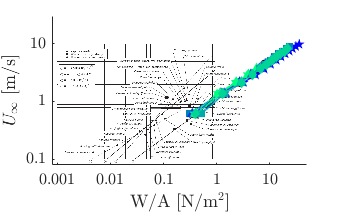


%set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
I = imread("seedscrop.PNG");
h = image([-3.05,0.6], [-1.06,1], I(end:-1:1,:,:));
uistack(h, "bottom");
xlim([-3.1,log10(50)]);
ylim([-1.1,log10(30)]);
f1.Units = "centimeters";
f1.Position = [1 1 8.9721 5.6534];
xticks([-3, -2, -1, 0, 1, 2])
xticklabels([0.001, 0.01, 0.1, 1, 10, 100]);
yticks([-1,0,1])
yticklabels([0.1,1,10]);
figureSaver(f1, "bruteFigs/wingloading.pdf");

## **Windtunnel displacement section**

% %Plotting the displacement of each series under flow
% f6 = figure("Name", "Disp t", 'Position', [50 150 450 300]); %Tensile t
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$w$ [m]");
% f7 = figure("Name", "Disp dr", 'Position', [50 150 450 300]); %Tensile dr
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$w$ [m]");
% f8 = figure("Name", "Disp n", 'Position', [50 150 450 300]); %Tensile n
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$w$ [m]");
% f9 = figure("Name", "Disp Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$w$ [m]");
% f10 = figure("Name", "Disp rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
% hold on;
% xlabel("$U$ [m/s]");
% ylabel("$w$ [m]");
% 
% torder = []; tplots = gobjects(length(ts), 1);
% drorder = [];drplots = gobjects(length(drmins), 1);
% norder = []; nplots = gobjects(length(ns), 1);
% Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
% rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);
% 
% for j = 1:length(all_names)
%     switch series{j}
%         case "base"
%             for i = 1:5
%                 switch i
%                     case 1
%                         figure(f6);
%                         ind = find(t(j) == ts);
%                         tplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
%                         torder(end+1) = ind;
%                         for k = 1:length(velocity{j})
%                             scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j});
%                         end
%                     case 2
%                         figure(f7);
%                         ind = find(drmin(j) == drmins);
%                         drplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
%                         
%                         drorder(end+1) = ind;
%                         for k = 1:length(velocity{j})
%                             scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%                         end
%                     case 3
%                         figure(f8);
%                         ind = find(n(j) == ns);
%                         nplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$n = $"+num2str(n(j)));
%                         
%                         norder(end+1) = ind;
%                         for k = 1:length(velocity{j})
%                             scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%                         end
%                     case 4
%                         figure(f9);
%                         ind = find(Ntheta(j) == Nthetas);
%                         Nthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
%                         
%                         Nthetaorder(end+1) = ind;
%                         for k = 1:length(velocity{j})
%                             scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%                         end
%                     case 5
%                         figure(f10);
%                         ind = find(rtheta(j) == rthetas);
%                         rthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$r_\theta = $"+num2str(rtheta(j)));
%                         
%                         rthetaorder(end+1) = ind;
%                         for k = 1:length(velocity{j})
%                             scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%                         end
%                 end
%             end
%         case "t"
%             figure(f6);
%             ind = find(t(j) == ts);
%             tplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
%             
%             torder(end+1) = ind;
%             for k = 1:length(velocity{j})
%                 scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%             end
%         case "dr"
%             figure(f7);
%             ind = find(drmin(j) == drmins);
%             drplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
%             
%             drorder(end+1) = ind;
%             for k = 1:length(velocity{j})
%                 scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%             end
%         case "n"
%             figure(f8);
%             ind = find(n(j) == ns);
%             nplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$n = $"+num2str(n(j)));
%             
%             norder(end+1) = ind;
%             for k = 1:length(velocity{j})
%                 scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%             end
%         case "Ntheta"
%             figure(f9);
%             ind = find(Ntheta(j) == Nthetas);
%             Nthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
%             
%             Nthetaorder(end+1) = ind;
%             for k = 1:length(velocity{j})
%                 scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%             end
%         case "rtheta"
%             figure(f10);
%             ind = find(rtheta(j) == rthetas);
%             rthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$r_\theta = $"+num2str(rtheta(j)));
%             
%             rthetaorder(end+1) = ind;
%             for k = 1:length(velocity{j})
%                 scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
%             end
%     end
% end
% %Reorder legends
% for i = 1:5
%     switch i
%         case 1
%             figure(f6);
%             legend(tplots, "Location", "best");
%             figureSaver(f6, "bruteFigs/dispt.pdf");
%         case 2
%             figure(f7);
%             legend(drplots, "Location", "best");
%             figureSaver(f7, "bruteFigs/dispdr.pdf");
%         case 3
%             figure(f8);
%             legend(nplots, "Location", "best");
%             figureSaver(f8, "bruteFigs/dispn.pdf");
%         case 4
%             figure(f9);
%             legend(Nthetaplots, "Location", "best");
%             figureSaver(f9, "bruteFigs/dispNtheta.pdf");
%         case 5
%             figure(f10);
%             legend(rthetaplots, "Location", "best");
%             figureSaver(f10, "bruteFigs/disprtheta.pdf");
%     end
% end

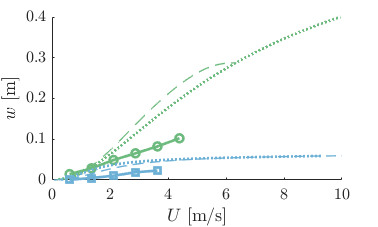

%Comparing dimensional drag results tests to numerical and semi-analytical
%results

f1 = figure("Name", "DragCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");

h = gobjects(6,1);

%AK8
%Exp
h(1) = plot(velocity{1}, extension{1}, "-o", "color", green, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
U = sqrt(CYsimK*KsimK*ell(1)/(CD0*rho*Rs(1)));
L = deltasimK*Rs(1)*ell(1);
h(2) = plot(U, L, ":", "color", green, "linewidth", 2, "DisplayName", "FIRM");

%Theo
U = sqrt(CYtheoK*Ktheo(1)*ell(1)/(CD0*rho*Rs(1)));
L = deltatheoK*Rs(1)*ell(1);
h(3) = plot(U, L, "--", "color", green, "linewidth", 1, "DisplayName", "Nonlinear Beam Model");

%AK10
%Exp
h(4) = plot(velocity{3}, extension{3}, "-s", "color", blue, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
U = sqrt(CYsimC*2*B(3)/(CD0*rho*Rs(3)^3));
L = deltasimC*Rs(3)*ell(3);
h(5) = plot(U, L, ":", "color", blue, "linewidth", 2, "DisplayName", "FIRM");

%Theo
h(6) = plot(UtheoC, LtheoC, "--", "color", blue, "linewidth", 1, "DisplayName", "Nonlinear Beam Model");

%legend(h, "location", "best");
%axis("tight");
xlim([0, 10]);
ylim([0, 0.4]);
f1.Units = "centimeters";
f1.Position = [1 1 10 6];
f1.Units = "points";
figureSaver(f1, "bruteFigs/DispCompModels.pdf");

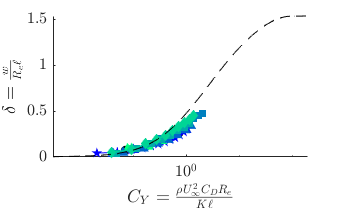

%Dimensionless displacement
f1 = figure("Name", "Dimensionless displacement", 'Position', [50 150 450 300]);
hold on;
xlabel("$C_Y = \frac{\rho U_\infty^2 C_DR_e}{K\ell}$")
ylabel("$\delta = \frac{w}{R_e\ell}$")

allx = [];
ally = [];

for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 2:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
            CYCD = CD0*(rho*velocity{j}(i)^2*Rs(j))/(Kexp(j)*ell(j));
        currentx(end+1) = CYCD;
        currenty(end+1) = extension{j}(i)/(Rs(j)*ell(j));% - Rc(j));
        allx(end+1) = currentx(end);
        ally(end+1) = currenty(end);
        end
    end
    
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 0.1);
end

%save("ExtensionExp.mat", "allx", "ally");

h = gobjects(4,1);

h = plot(CYsimK, deltasimK, "--k", "DisplayName", "FIRM");
deltasimKModel = @(CYCD) dragratio(CYsimK, deltasimK, CYCD);
%h(2) = plot(CYsimKG, deltasimKG, "--r", "DisplayName", "FIRM - With Gravity");

% CYtheoK = CD0*rho*Rs(1)^3*UtheoK.^2/(B(1)*Kbar(1)*ell(1));
% deltatheoK = -LtheoK./(Rs(1)*ell(1));
% h(2) = plot(CYtheoK, deltatheoK, "-k", "DisplayName", "Nonlinear Beam Model");

% c = @(x, CYCD) 1+x(1)*CYCD.^x(2);
% deltasimKModel = @(x, CYCD) dragratio(CYsimK, deltasimK, CYCD).*c(x, CYCD);
% 
% x1 = fminsearch(@(x) getRegressionError(allx, ally, @(CYCD) deltasimKModel(x, CYCD)), [1, 0.5]);
% c = @(CYCD) b(x1, CYCD);
% deltasimKModel = @(CYCD) deltasimKModel(x1, CYCD);
% h(2) = plot(CYsimK, deltasimKModel(CYsimK), "--", "color", blue, "DisplayName", "FIRM - Corrected");

%legend(h, "Location", "best");

set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
%xlim([10^(0),200])
f1.Units = "centimeters";
f1.Position = [1 1 9, 5.5];
figureSaver(f1, "bruteFigs/dimensionlessdisp.pdf");

## **Design process section**

%Design map
%KL vs W vs U
f1 = figure("Name", "DesignMap", 'Position', [50 150 450 300]);
hold on;
xlabel("$WR_e/\alpha B$")
ylabel("$\bar{K}\ell$")

Kbarell = linspace(1, 7, 100);
WRB = linspace(10, 1000, 105);

[WRB, KL] = meshgrid(WRB, Kbarell);

z = WRB;
for i = 1:length(WRB(:,1))
    for j = 1:length(WRB(1,:))
        CY = fsolve(@(CY) RsimKModel(CY)*CY*KL(i,j)/2 - WRB(i,j), 10);
        z(i,j) = CY*KL(i,j);
    end
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

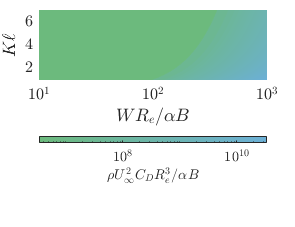


contourf(WRB, KL, z, 1000, 'EdgeColor', 'none');
colormap(greenmap(100));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\rho U_\infty^2 C_D R_e^3/\alpha B$';
c.Location = "southoutside";
set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
set(gca,'ColorScale','log')
axis("tight")
f1.Units = "centimeters";
f1.Position = [1 1 7.8173, 6];
figureSaver(f1, "bruteFigs/designmap.png");

%Dimensioning the parachute
%From the previous graph, we want the highest KL possible
%as for a constant WRB, a higher KL means lower CYCD*KL
%Let's assume KL = 5.7 (safety factor)

WRB = linspace(10, 10^3, 500);
KL = 6.25;

CYCDKL = WRB;

for i = 1:length(WRB)
    if i == 1
        CYCD = fsolve(@(CYCD) RsimKModel(CYCD) - WRB(i)/(0.5*CYCD*KL), 10);
    else
        CYCD = fsolve(@(CYCD) RsimKModel(CYCD) - WRB(i)/(0.5*CYCD*KL), CYCDKL(i-1)/KL);
    end
    CYCDKL(i) = CYCD*KL;
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

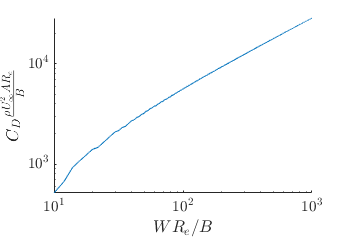


f1 = figure("Name", "DesignMap", 'Position', [50 150 450 300]);
hold on;
xlabel("$WR_e/B$")
ylabel("$C_D\frac{\rho U_\infty^2 AR_e}{B}$")

plot(WRB, CYCDKL);
axis("tight");
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
f1.Units = "centimeters";
f1.Position = [1 1 8.6171+dh, 6.1146+dw];

%figureSaver(f1, "bruteFigs/dimensionlessdisp.pdf");

%We therefore approximate that CYCDKL grows as CYCDKL \simapprox
%WRB^1.2521, which we find that we use the maximum B and we need to
%test what biggest size Re allows a KL of 5.7 (and the allowed energy ratio) in our laser cutter

%What maximum radius is allowed in the laser cutter according to the number
%of angular cuts
Ntheta = 3:1:30;
Re = zeros(length(Ntheta), 1);

lasercutterwidth = 0.5;
lasercutterlength = 1;

for i = 1:length(Ntheta)
    if Ntheta(i) == 3
        lengthradius = lasercutterlength/(1+sin(pi/6));
        widthradius = lasercutterwidth;
        Re(i) = min(lengthradius, widthradius);
    elseif Ntheta(i) == 4
        Re(i) = lasercutterwidth; 
    else
        lengthradius = lasercutterlength;
        widthradius = lasercutterwidth/sin(2*pi/Ntheta(i));
        Re(i) = min(lengthradius, widthradius);
    end
end

[Re, ind] = unique(Re);
Ntheta = Ntheta(ind);

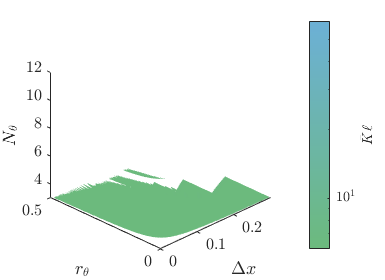

%Feasable space for the solutions
Ri = 3E-2;
drmin = 1.35E-3;
dx = linspace(0, 0.3, 500);
rtheta = linspace(0, 0.5, 500);

epsKC = ones(length(rtheta), length(dx), length(Ntheta))*NaN;
Kbar = epsKC;
ell = epsKC;
Kbarell = epsKC;
Nrs = epsKC;
correctmode = zeros(length(rtheta), length(dx), length(Ntheta));

for i = 1:length(dx)
    for j = 1:length(rtheta)
        for k = 1:length(Ntheta)
            beta = Ri/Re(k);
            dxmin = drmin/Re(k);
            if Ntheta(k) < floor(2*pi*dx(i)*Re(k)*rtheta(j)/(drmin*(1+rtheta(j)))) && rtheta(j) ~= 0 && dx(i) > dxmin
                [Kbari, elli, epsKCi] = getKirigamiValues(Re(k), Ri, drmin, dx(i), 1, Ntheta(k), rtheta(j));
                epsKC(j,i,k) = epsKCi;
                Kbar(j,i,k) = Kbari;
                ell(j,i,k) = elli;
                Kbarell(j,i,k) = Kbar(j,i,k)*ell(j,i,k);
                if Kbarell(j,i,k) < 6.5 && epsKC(j,i,k) > 9E-6
                    correctmode(j,i,k) = Ntheta(k);
                else
                    Kbar(j,i,k) = NaN;
                    ell(j,i,k) = NaN;
                    Kbarell(j,i,k) = NaN;
                    epsKC(j,i,k) = NaN;
                end
            end
        end
    end
end

f1 = figure("Name", "PotentialSpace");
hold on;
xlabel("$\Delta x$");
ylabel("$r_\theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
nslices = 0;
for k = 1:length(Ntheta)
    if any(any(Kbarell(:,:,k) < 6))
        nslices = nslices + 1;
    end
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbarell(:,:,k), 'EdgeColor', 'none');
end
colormap(greenmap(1000));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}\ell$';
caxis([6, inf])
view([-45,30]);
set(gca,'ColorScale','log')
f1.Units = "centimeters";
f1.Position = [1 1 1.1*9.2638, 1.1*6.7396];

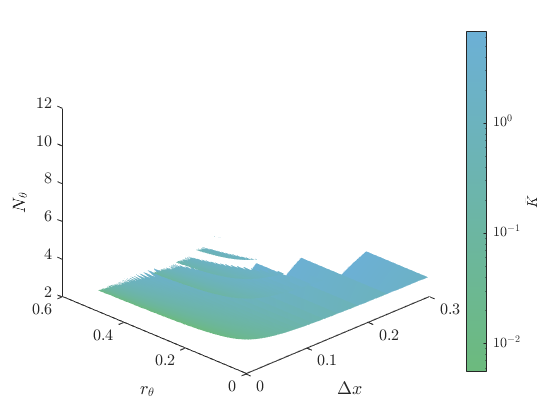

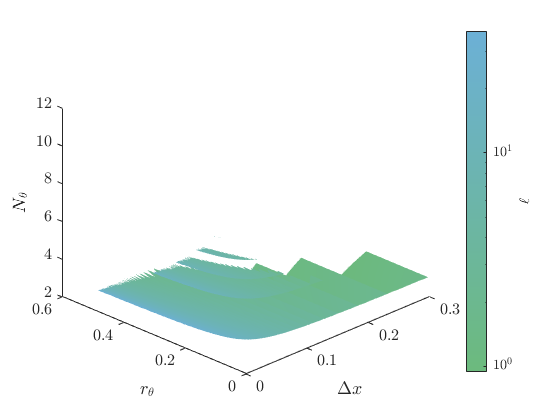

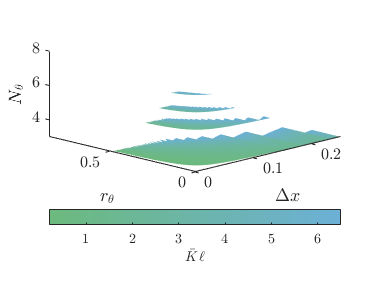


%figureSaver(f1, "bruteFigs/potentialSpace.pdf");
f1 = figure("Name", "PotentialSpaceStiffness");
hold on;
xlabel("$\Delta x$");
ylabel("$r_\theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbar(:,:,k), 'EdgeColor', 'none');
end
colormap(greenmap(1000));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}$';
set(gca,'ColorScale','log')
view([-45,30]);

f1 = figure("Name", "PotentialSpaceExtension");
hold on;
xlabel("$\Delta x$");
ylabel("$r_\theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), ell(:,:,k), 'EdgeColor', 'none');
end
colormap(greenmap(1000));
c = colorbar();
set(gca,'ColorScale','log')
c.Label.Interpreter = 'latex';
c.Label.String = '$\ell$';
view([-45,30]);

f1 = figure("Name", "SpaceKL");
hold on;
xlabel("$\Delta x$");
ylabel("$r_\theta$");
zlabel("$N_\theta$");
xlim([0, 0.25]);
ylim([0, 0.85]);
zlim([3, 8]);
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbar(:,:,k).*ell(:,:,k), 'EdgeColor', 'none');
end
colormap(greenmap(1000));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}\ell$';
c.Location = "southoutside";
%set(gca,'ColorScale','log')
view([-45,30]);
f1.Units = "centimeters";
f1.Position = [1 1 1.1*9.0838, 7.7296];
figureSaver(f1, "bruteFigs/potentialSpace.png");

%Extract which Nthetas have KL and eps okay
correctNtheta = [];

for i = 1:length(dx)
    for j = 1:length(rtheta)
        for k = 1:length(Ntheta)
            if isnumeric(correctmode(j,i,k)) && correctmode(j,i,k) ~= 0
                correctNtheta(end+1) = correctmode(j,i,k);
            end
        end
    end
end

Nthetas = unique(correctNtheta);
k = length(Nthetas)-1;
Rei = Re(k);
Nthetai = Ntheta(k);

%Get closest KL
errKL = realmax;

for i = 1:length(dx)
    for j = 1:length(rtheta)
        if abs(Kbarell(j,i,k) - KL) < errKL
            bestx = [dx(i), rtheta(j)];
            errKL = abs(Kbarell(j,i,k) - KL);
        end
    end
end

%We have the chosen Re and the chosen Ntheta
%We know we maximise B
%We look for the pair (dx, rtheta) that fit KL and find U
options = optimoptions("fsolve", "Algorithm", "levenberg-marquardt");

[x, fval, exitflag, output] = fsolve(@(x) getKbarell(Rei, Ri/Rei, drmin/Rei, x(1), 1, x(2), Nthetai) - KL, bestx, options);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


dx = x(1);
rtheta = x(2);
Ntheta = Nthetai;
Re = Rei;



[Kbar, ell, eps] = getKirigamiValues(Rei, Ri, drmin, dx, 1, Nthetai, rtheta);
if dx > dxmin/Re && dx < 1-Ri/Re && Ntheta > 2 && Ntheta <= floor(2*pi*dx*Re*rtheta/drmin/(1+rtheta)) && rtheta > 0 && rtheta < 1
    fprintf("This parachute respects manufacturability constraints");
else
    fprintf("This parachute does not respect manufacturability constraints");
end

This parachute respects manufacturability constraints

fprintf("This parachute has a Kbarell of %f and an energy ratio of %e, therefore %f %% over the energy requirements", Kbar*ell, eps, (eps - 9E-6)/9E-8);

This parachute has a Kbarell of 6.250000 and an energy ratio of 1.335365e-05, therefore 48.373879 % over the energy requirements


%Fluid
rho = 1.225;
CD = 1.1;

%Payload
m = 1; %kg
g = 9.81; %N/kg

%Material
E = 3E9;
t = 317.5E-6;
B = E*t^3/12;

W = m*g;

alpha = 10^pK(2);

CYCD = fsolve(@(CY) RsimKModel(CY)*CY*Kbar*ell/2 - W*Re/(alpha*B), 1);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fprintf("The terminal velocity of this parachute reaches a Cauchy number of %f", CYCD);

The terminal velocity of this parachute reaches a Cauchy number of 1470.604103

U = sqrt(CYCD*KL*B/(rho*CD*pi*Rei^3));
fprintf("This parachute would fall at a terminal velocity of %f m/s\n", U);

This parachute would fall at a terminal velocity of 8.149836 m/s


delta = deltasimKModel(CYCD);
fprintf("This parachute would elongate by delta = %f, i.e., %f m\n", delta, delta*Rei*ell);

This parachute would elongate by delta = 1.489518, i.e., 4.847496 m


fprintf("Final dimensions: Re = %f m Ri = %f m t = %e m E = %e Pa dx = %f Ntheta = %f rtheta = %f", Re, Ri, t, E, dx, Ntheta, rtheta);

Final dimensions: Re = 0.639524 m Ri = 0.030000 m t = 3.175000e-04 m E = 3.000000e+09 Pa dx = 0.031265 Ntheta = 7.000000 rtheta = 0.154308

%Dimensioning final parachute for a go-pro
%Maximum terminal velocity of a go-pro is 28m/s
%https://www.quora.com/What-g-force-can-a-GoPro-withstand-if-launched-from-a-cannon

%Skydivers touch the ground around 5-6m/s
%https://www.explainthatstuff.com/how-parachutes-work.html#:~:text=Parachutes%20are%20designed%20to%20reduce,feet%20and%20walk%20away%20unharmed.